Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |       18.75% |       12.82% |       1.5088 |       1.3362 |      1.0000e-04 |
|       1 |          10 |       00:00:22 |      100.00% |       94.78% |       0.0507 |       0.2289 |      1.0000e-04 |
|       1 |          20 |       00:00:30 |      100.00% |       95.09% |       0.0131 |       0.2117 |      1.0000e-04 |
|       1 |          30 |       00:00:38 |      100.00% |       94.15% |       0.0278 |   

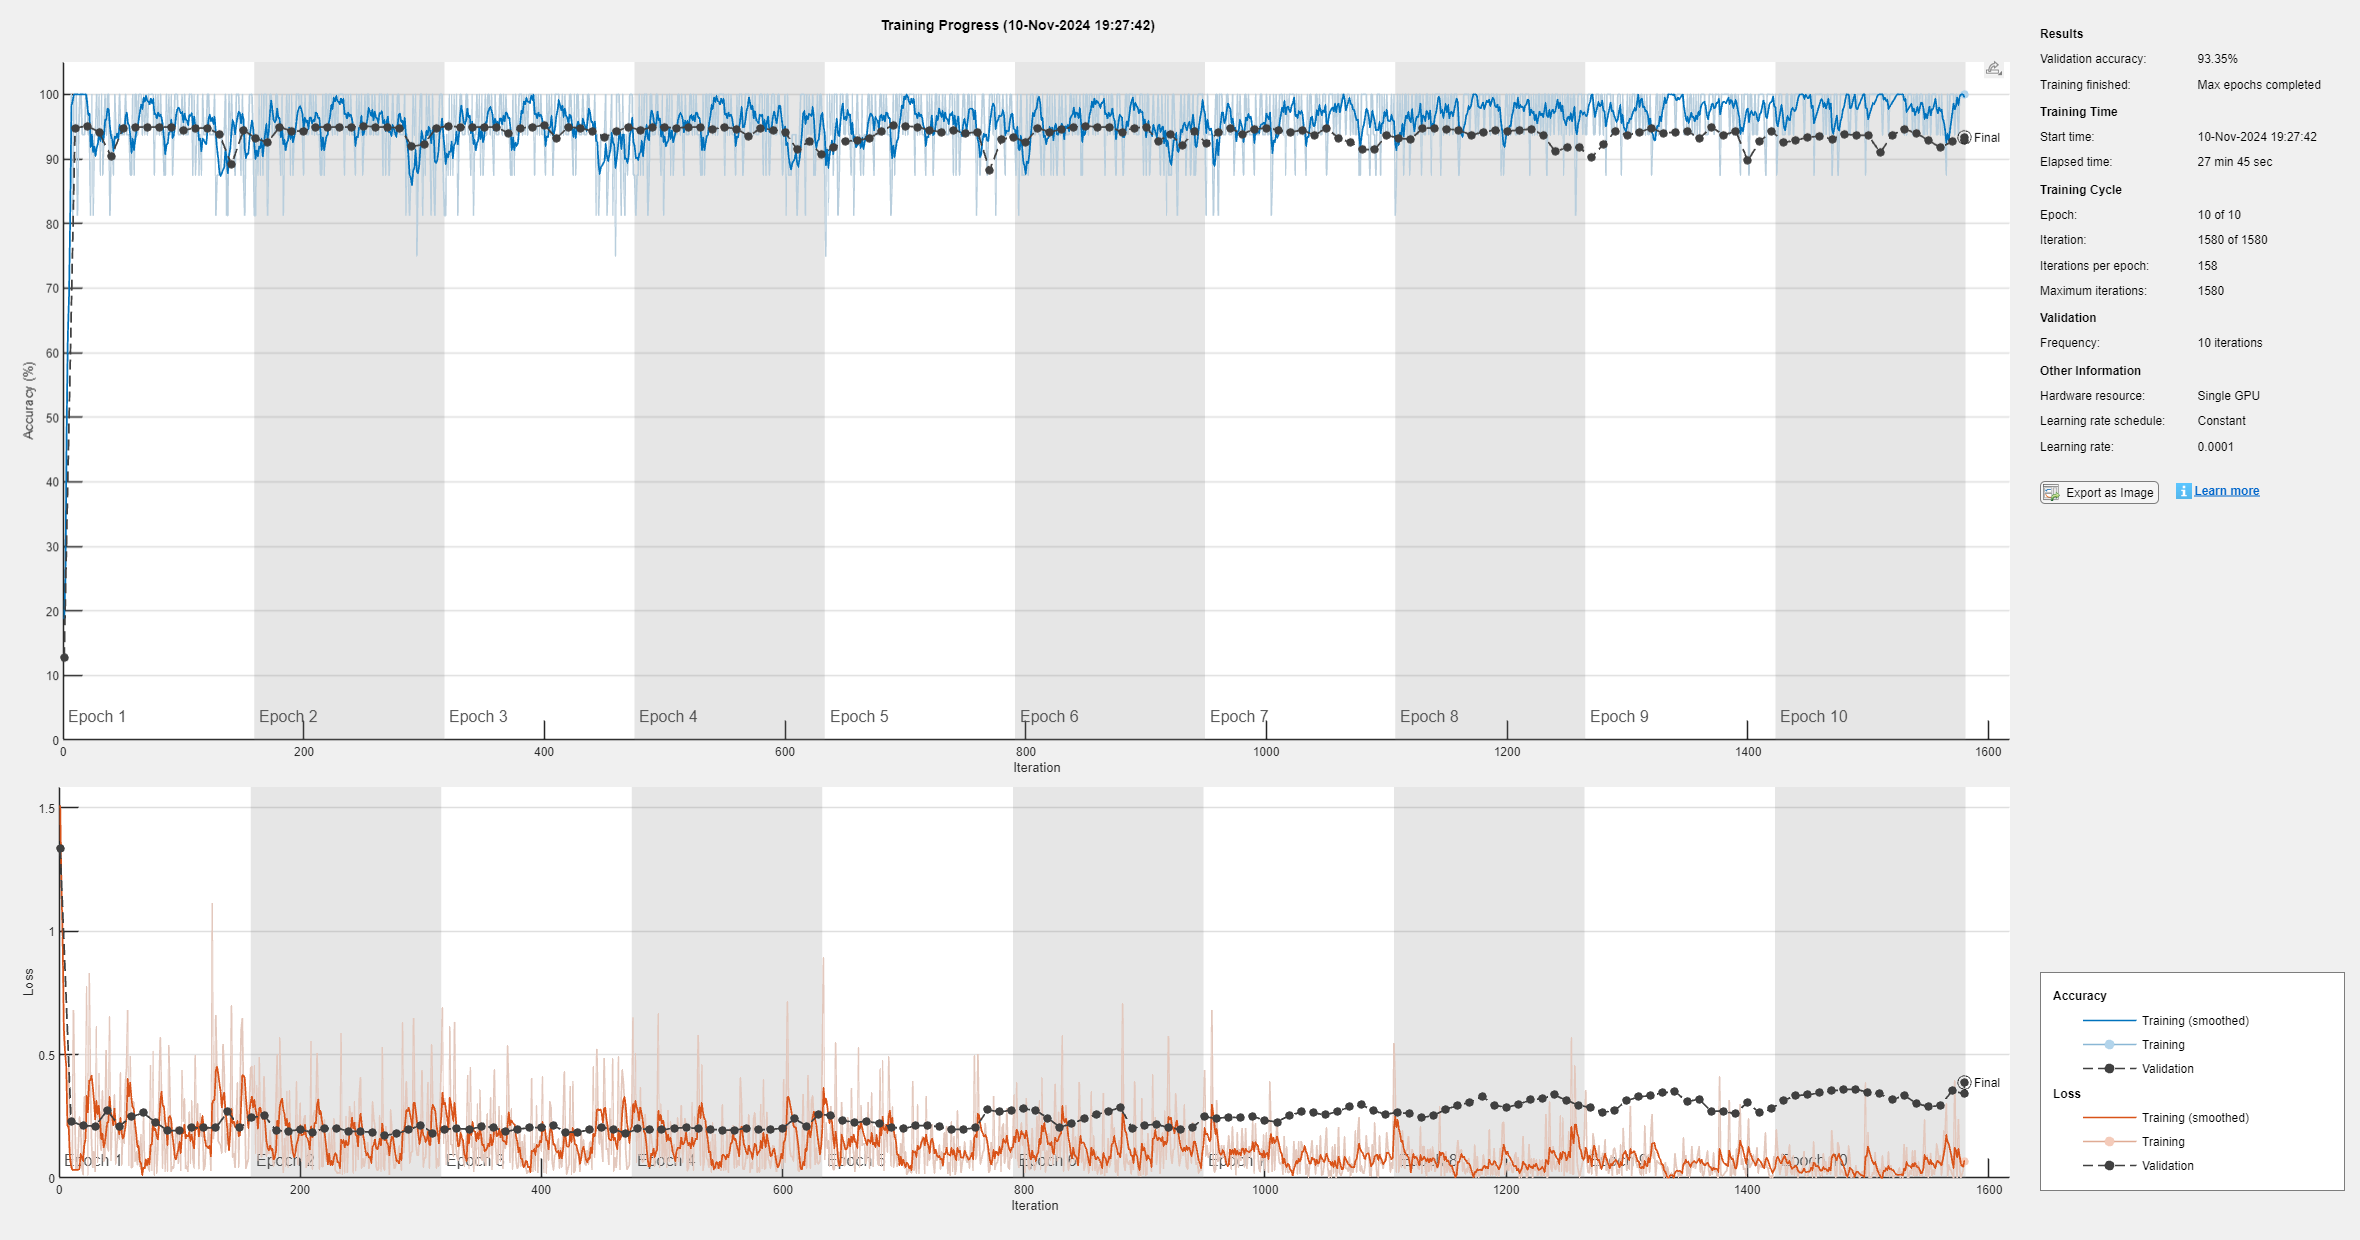

% Paths and Parameters
imageFolder = 'training_img_spectrograms';  % Folder with spectrogram images
labelFile = 'labels.csv';  % CSV file with labels

% Load Labels from CSV
labelsTbl = readtable(labelFile);  % Load CSV with headers
labelsTbl.file_name = strcat(labelsTbl.file_name, '.png');  % Append .png to filenames

% Create imageDatastore for images
imds = imageDatastore(imageFolder, 'FileExtensions', '.png');

% Link labels to images using file names
[~, fileNames] = fileparts(imds.Files);
[~, labelFileNames] = fileparts(labelsTbl.file_name);
[isMember, idx] = ismember(fileNames, labelFileNames);
imds.Files = imds.Files(isMember);  % Filter files that have labels
imds.Labels = categorical(labelsTbl.target(idx(isMember)));  % Set labels from CSV

% Resize images to match network input size
imageSize = [224 224];  % ResNet input size
imds.ReadFcn = @(x) imresize(imread(x), imageSize);

% Split Data into Training and Validation Sets
[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.8, 'randomized');

%% Load Pre-trained ResNet Model and Modify for Binary Classification

% Load the pre-trained ResNet-50 model
net = resnet50;

% Replace the last layers of ResNet-50 to fit binary classification
lgraph = layerGraph(net);
numClasses = 2;

% Remove the last three layers (fully connected, softmax, and classification)
lgraph = removeLayers(lgraph, {'fc1000', 'fc1000_softmax', 'ClassificationLayer_fc1000'});

% Add new layers for binary classification
newLayers = [
    fullyConnectedLayer(numClasses, 'Name', 'fc_binary')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];

% Connect new layers to the graph
lgraph = addLayers(lgraph, newLayers);
lgraph = connectLayers(lgraph, 'avg_pool', 'fc_binary');

%% Data Augmentation and Training Options

% Define data augmentation for training data
imageAugmenter = imageDataAugmenter( ...
    'RandRotation', [-10, 10], ...
    'RandXTranslation', [-5, 5], ...
    'RandYTranslation', [-5, 5], ...
    'RandXScale', [0.9, 1.1], ...
    'RandYScale', [0.9, 1.1]);

% Augment the training images
augimdsTrain = augmentedImageDatastore(imageSize, imdsTrain, 'DataAugmentation', imageAugmenter);
augimdsValidation = augmentedImageDatastore(imageSize, imdsValidation);

% Training options
options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-4, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 16, ...
    'ValidationData', augimdsValidation, ...
    'ValidationFrequency', 10, ...
    'Verbose', true, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'auto');

%% Train the Network

% Train the model
trainedNet = trainNetwork(augimdsTrain, lgraph, options);

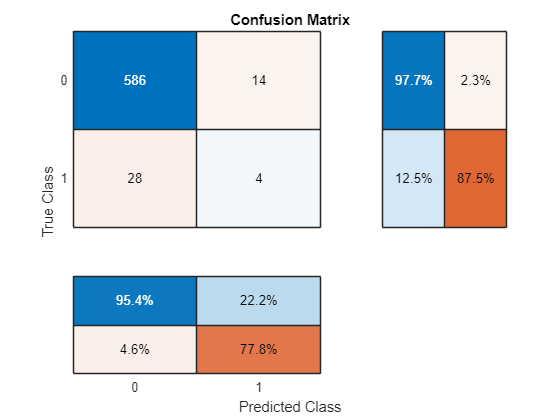


%% Evaluate Model Performance and Plot AUC-ROC and Confusion Matrix

% Classify validation images and get scores
[YPred, scores] = classify(trainedNet, augimdsValidation);
YValidation = imdsValidation.Labels;

% Plot confusion matrix
figure;
confusionchart(YValidation, YPred, 'Title', 'Confusion Matrix', ...
               'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized');

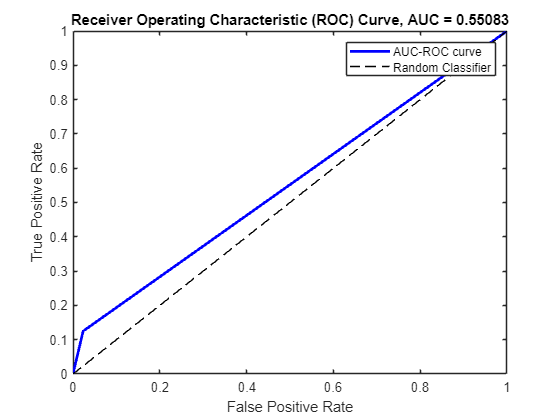


% Compute AUC-ROC curve
[~, scoresPos] = max(scores, [], 2);
positiveClass = categorical("1");  % Adjust if needed
YValidationNumeric = double(YValidation == positiveClass);

% Compute ROC curve and AUC
[fpr, tpr, ~, aucValue] = perfcurve(YValidationNumeric, scoresPos, 1);

% Plot ROC curve
figure;
plot(fpr, tpr, 'b-', 'LineWidth', 2);
hold on;
plot([0 1], [0 1], 'k--');  % Diagonal line for random classifier
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['Receiver Operating Characteristic (ROC) Curve, AUC = ' num2str(aucValue)]);
legend('AUC-ROC curve', 'Random Classifier');
hold off;

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       68.75% |       94.94% |       0.7496 |       0.2254 |      5.0000e-05 |
|       1 |          10 |       00:00:09 |      100.00% |       94.94% |       0.0008 |       0.3760 |      5.0000e-05 |
|       1 |          20 |       00:00:14 |       81.25% |       94.78% |       0.3065 |       0.2798 |      5.0000e-05 |
|       1 |          30 |       00:00:19 |      100.00% |       94.94% |       0.0166 |   

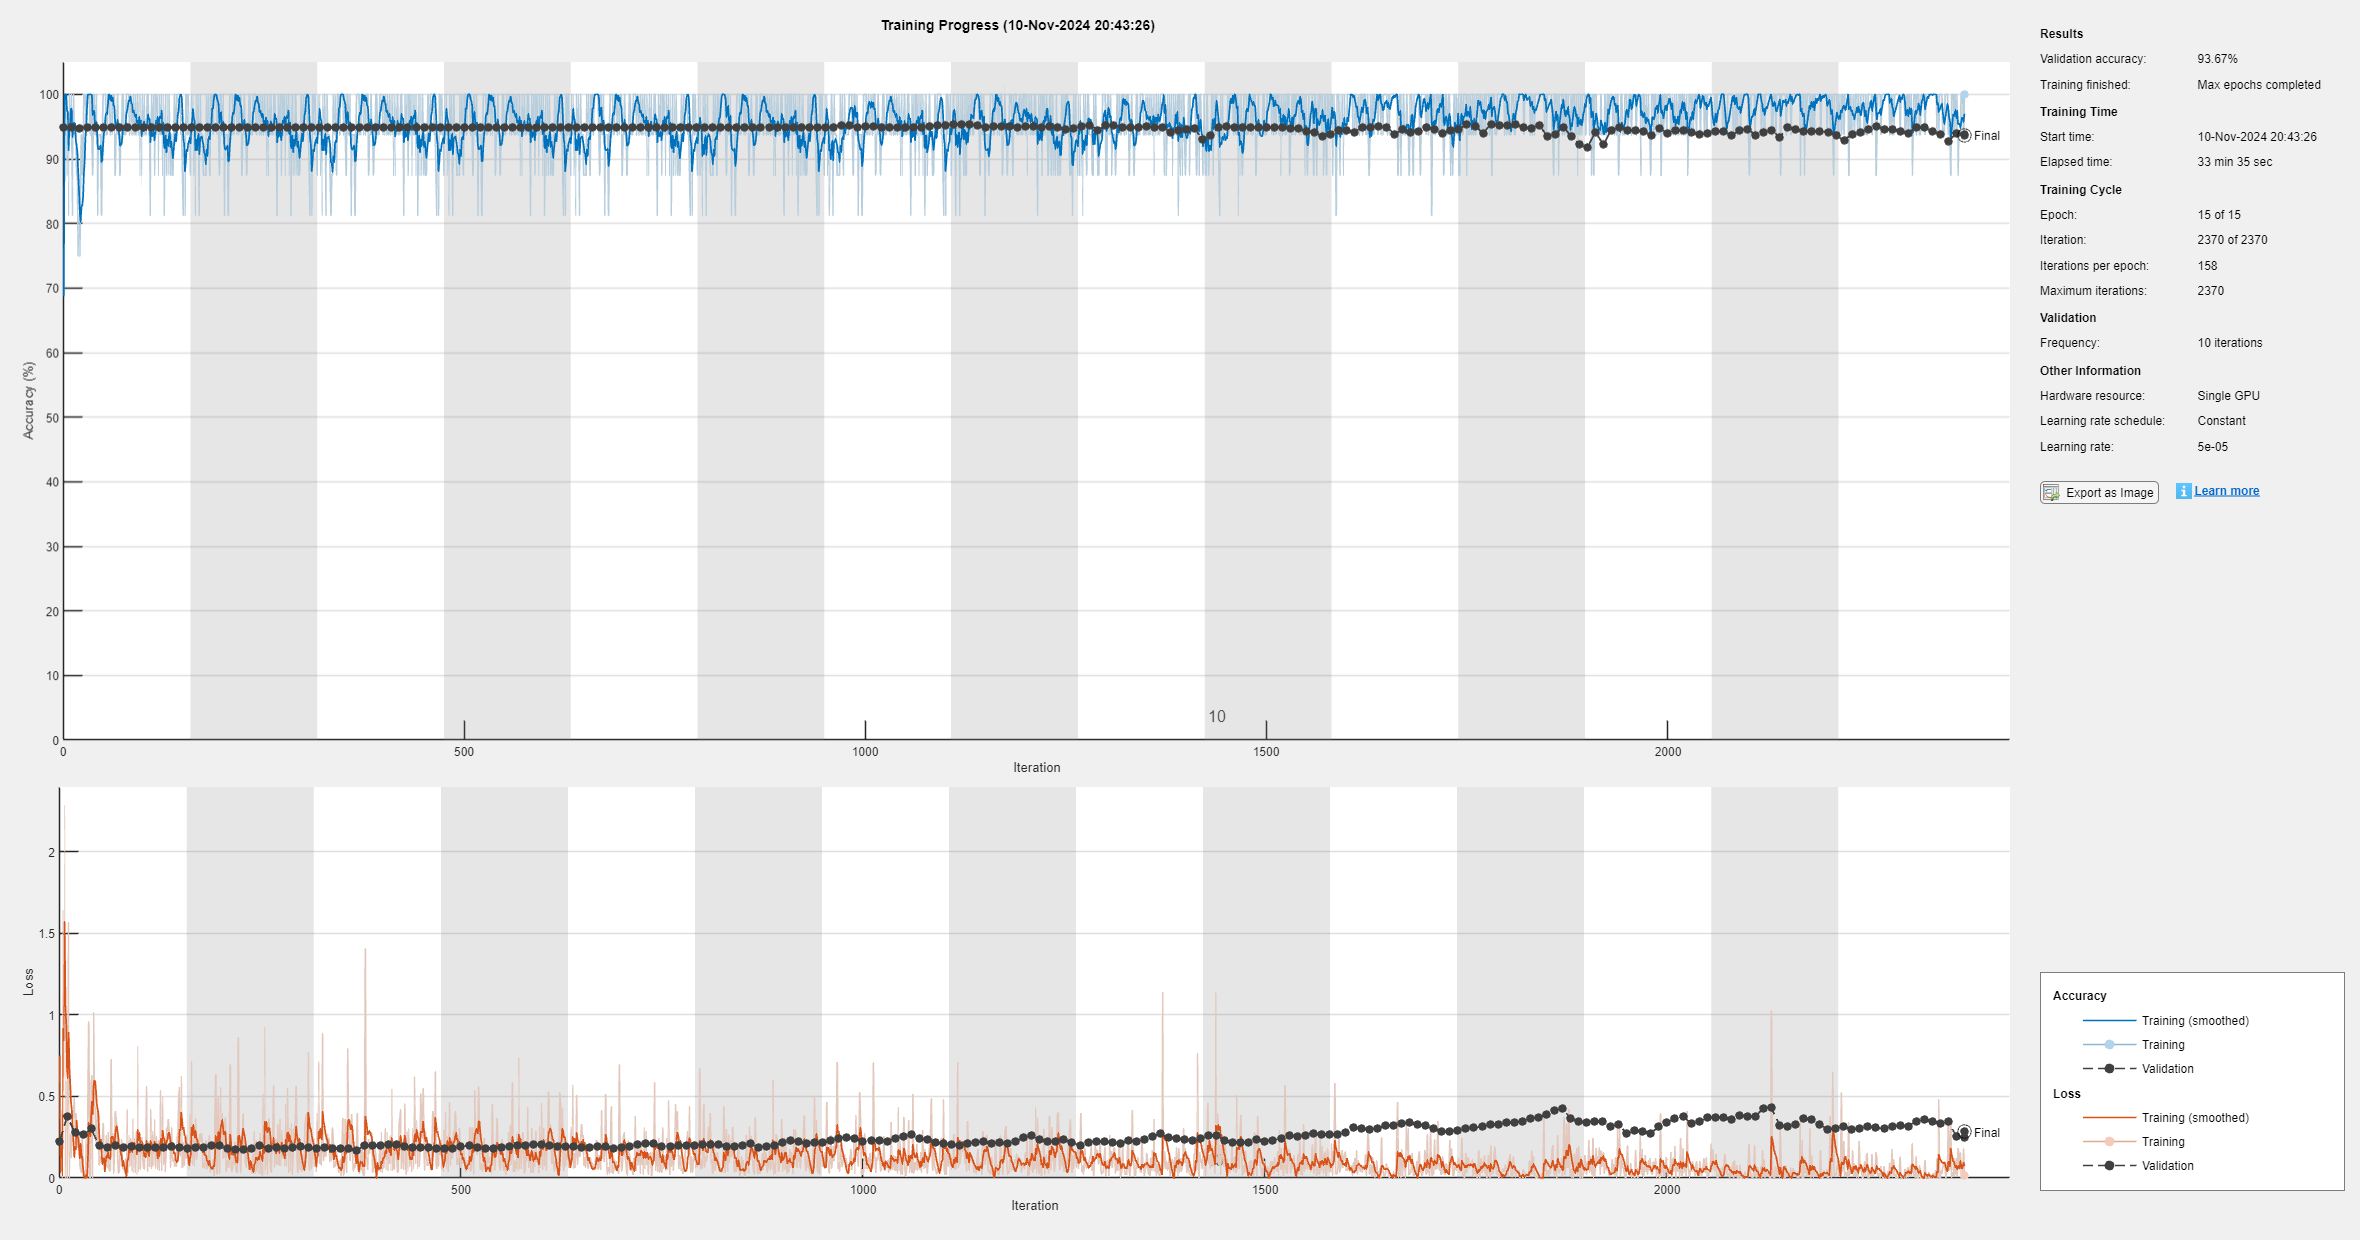

% Paths and Parameters
imageFolder = 'training_img_spectrograms';  % Folder with spectrogram images
labelFile = 'labels.csv';  % CSV file with labels

% Load Labels from CSV
labelsTbl = readtable(labelFile);  % Load CSV with headers
labelsTbl.file_name = strcat(labelsTbl.file_name, '.png');  % Append .png to filenames

% Create imageDatastore for images
imds = imageDatastore(imageFolder, 'FileExtensions', '.png');

% Link labels to images using file names
[~, fileNames] = fileparts(imds.Files);
[~, labelFileNames] = fileparts(labelsTbl.file_name);
[isMember, idx] = ismember(fileNames, labelFileNames);
imds.Files = imds.Files(isMember);  % Filter files that have labels
imds.Labels = categorical(labelsTbl.target(idx(isMember)));  % Set labels from CSV

% Resize images to match network input size
imageSize = [224 224];  % ResNet input size
imds.ReadFcn = @(x) imresize(imread(x), imageSize);

% Split Data into Training and Validation Sets
[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.8, 'randomized');

%% Load Pre-trained ResNet Model and Customize

% Load the pre-trained ResNet-50 model
net = resnet50;

% Convert the network into a layer graph
lgraph = layerGraph(net);
numClasses = 2;

% Remove the last layers of ResNet-50
lgraph = removeLayers(lgraph, {'fc1000', 'fc1000_softmax', 'ClassificationLayer_fc1000'});

% Add new layers for binary classification
newLayers = [
    fullyConnectedLayer(256, 'Name', 'fc1', 'WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10)
    reluLayer('Name', 'relu1')
    dropoutLayer(0.5, 'Name', 'dropout1')  % Dropout to prevent overfitting
    fullyConnectedLayer(numClasses, 'Name', 'fc_binary')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];

% Add the new layers to the graph
lgraph = addLayers(lgraph, newLayers);

% Connect the new layers to the rest of the network
lgraph = connectLayers(lgraph, 'avg_pool', 'fc1');

%% Data Augmentation and Training Options

% Define data augmentation for training data
imageAugmenter = imageDataAugmenter( ...
    'RandRotation', [-15, 15], ...
    'RandXTranslation', [-10, 10], ...
    'RandYTranslation', [-10, 10], ...
    'RandXScale', [0.8, 1.2], ...
    'RandYScale', [0.8, 1.2]);

% Augment the training images
augimdsTrain = augmentedImageDatastore(imageSize, imdsTrain, 'DataAugmentation', imageAugmenter);
augimdsValidation = augmentedImageDatastore(imageSize, imdsValidation);

% Training options with a lower learning rate and more epochs
options = trainingOptions('adam', ...
    'InitialLearnRate', 5e-5, ...  % Lower learning rate
    'MaxEpochs', 15, ...  % Increase the number of epochs
    'MiniBatchSize', 16, ...
    'ValidationData', augimdsValidation, ...
    'ValidationFrequency', 10, ...
    'Verbose', true, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'auto');

%% Train the Network

% Train the model
trainedNet = trainNetwork(augimdsTrain, lgraph, options);

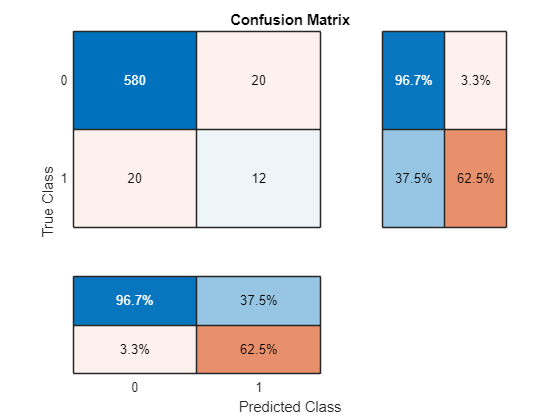


%% Evaluate Model Performance and Plot AUC-ROC and Confusion Matrix

% Classify validation images and get scores
[YPred, scores] = classify(trainedNet, augimdsValidation);
YValidation = imdsValidation.Labels;

% Plot confusion matrix
figure;
confusionchart(YValidation, YPred, 'Title', 'Confusion Matrix', ...
               'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized');

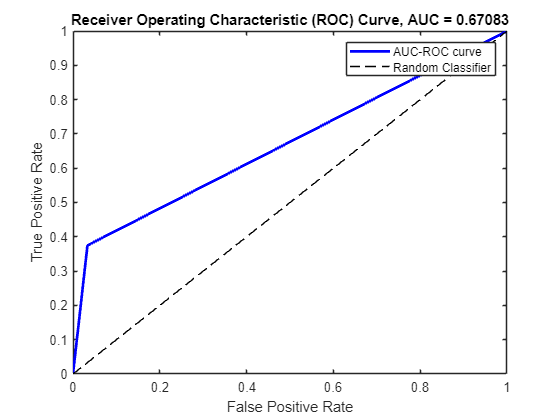


% Compute AUC-ROC curve
[~, scoresPos] = max(scores, [], 2);
positiveClass = categorical("1");  % Adjust if needed
YValidationNumeric = double(YValidation == positiveClass);

% Compute ROC curve and AUC
[fpr, tpr, ~, aucValue] = perfcurve(YValidationNumeric, scoresPos, 1);

% Plot ROC curve
figure;
plot(fpr, tpr, 'b-', 'LineWidth', 2);
hold on;
plot([0 1], [0 1], 'k--');  % Diagonal line for random classifier
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['Receiver Operating Characteristic (ROC) Curve, AUC = ' num2str(aucValue)]);
legend('AUC-ROC curve', 'Random Classifier');
hold off;

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:15 |        6.25% |       94.94% |       1.7273 |       0.3897 |      1.0000e-04 |
|       1 |          20 |       00:00:24 |      100.00% |       94.94% |       0.0006 |       0.5183 |      1.0000e-04 |
|       1 |          40 |       00:00:31 |       87.50% |       94.94% |       0.5829 |       0.2071 |      1.0000e-04 |
|       1 |          50 |       00:00:34 |      100.00% |              |       0.0589 |   

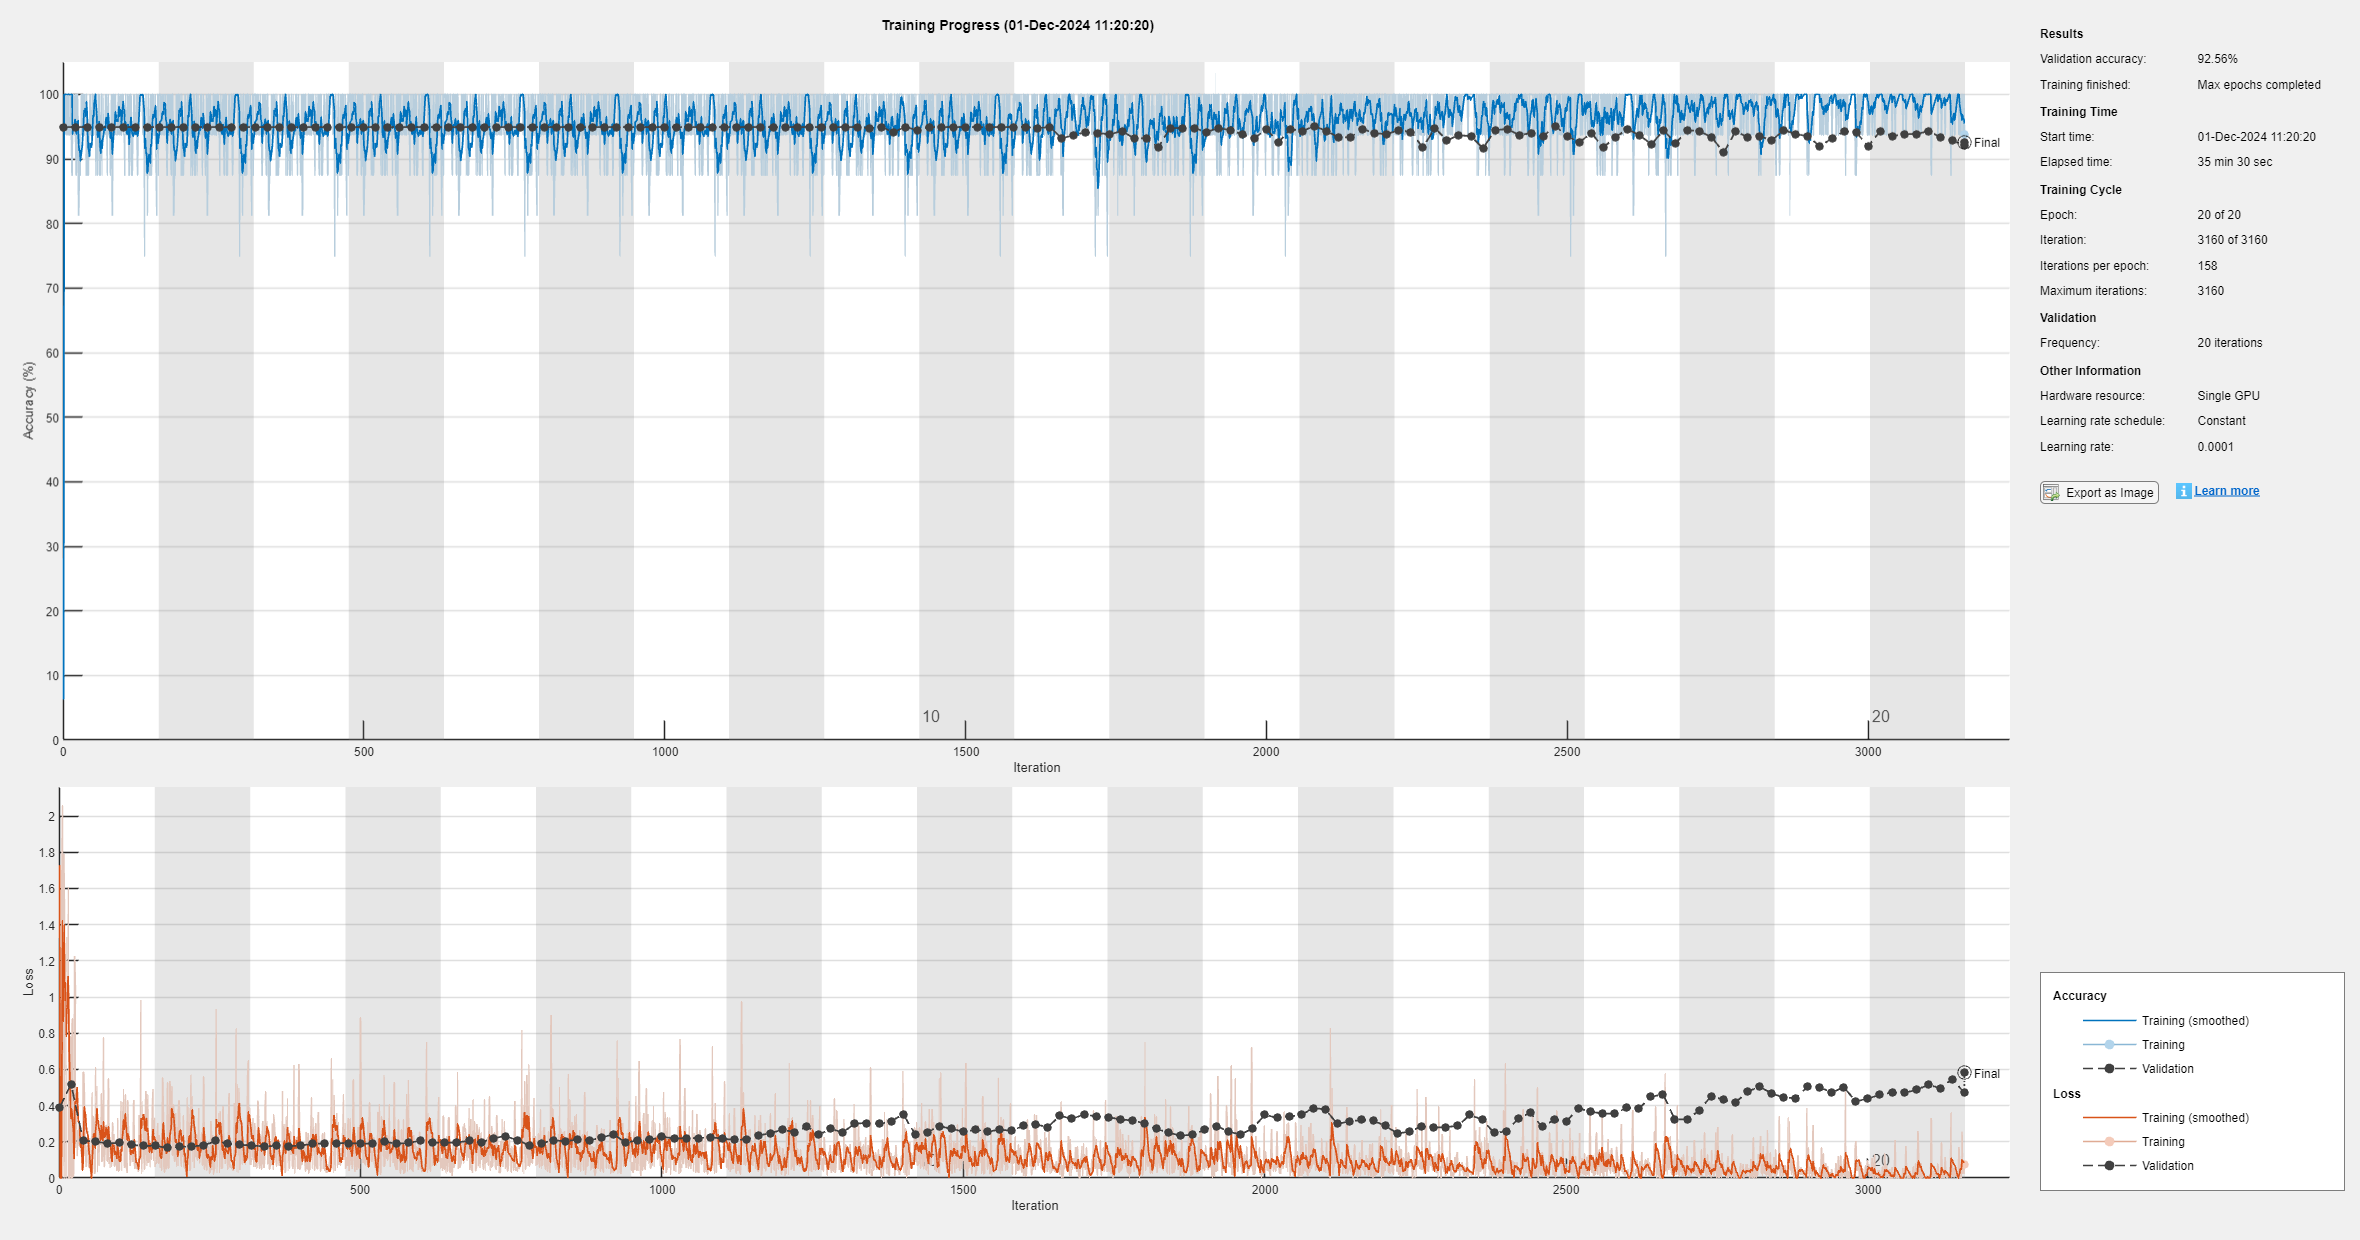

%% Paths and Parameters
imageFolder = 'training_img_spectrograms';  % Folder with spectrogram images
labelFile = 'labels.csv';  % CSV file with labels

% Load Labels from CSV
labelsTbl = readtable(labelFile);  % Load CSV with headers
labelsTbl.file_name = strcat(labelsTbl.file_name, '.png');  % Append .png to filenames

% Create imageDatastore for images
imds = imageDatastore(imageFolder, 'FileExtensions', '.png');

% Link labels to images using file names
[~, fileNames] = fileparts(imds.Files);
[~, labelFileNames] = fileparts(labelsTbl.file_name);
[isMember, idx] = ismember(fileNames, labelFileNames);
imds.Files = imds.Files(isMember);  % Filter files that have labels
imds.Labels = categorical(labelsTbl.target(idx(isMember)));  % Set labels from CSV

% Resize images to match network input size
imageSize = [224 224];  % ResNet input size
imds.ReadFcn = @(x) imresize(imread(x), imageSize);

% Split Data into Training and Validation Sets
[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.8, 'randomized');

%% Load Pre-trained ResNet Model and Customize

% Load the pre-trained ResNet-50 model
net = resnet50;

% Convert the network into a layer graph
lgraph = layerGraph(net);
numClasses = 2;

% Remove the last layers of ResNet-50
lgraph = removeLayers(lgraph, {'fc1000', 'fc1000_softmax', 'ClassificationLayer_fc1000'});

% Add new layers for binary classification
newLayers = [
    fullyConnectedLayer(256, 'Name', 'fc1', 'WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10)
    reluLayer('Name', 'relu1')
    dropoutLayer(0.3, 'Name', 'dropout1')  % Reduced dropout to encourage nuanced learning
    fullyConnectedLayer(numClasses, 'Name', 'fc_binary')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];

% Add the new layers to the graph
lgraph = addLayers(lgraph, newLayers);

% Connect the new layers to the rest of the network
lgraph = connectLayers(lgraph, 'avg_pool', 'fc1');

%% Data Augmentation and Training Options

% Define data augmentation for training data
imageAugmenter = imageDataAugmenter( ...
    'RandRotation', [-15, 15], ...
    'RandXTranslation', [-10, 10], ...
    'RandYTranslation', [-10, 10], ...
    'RandXScale', [0.8, 1.2], ...
    'RandYScale', [0.8, 1.2]);

% Augment the training images
augimdsTrain = augmentedImageDatastore(imageSize, imdsTrain, 'DataAugmentation', imageAugmenter);
augimdsValidation = augmentedImageDatastore(imageSize, imdsValidation);

% Training options with a lower learning rate and more epochs
options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-4, ...  % Slightly higher learning rate
    'MaxEpochs', 20, ...  % Increase the number of epochs
    'MiniBatchSize', 16, ...
    'ValidationData', augimdsValidation, ...
    'ValidationFrequency', 20, ...
    'Verbose', true, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'auto');

%% Train the Network

% Train the model
trainedNet = trainNetwork(augimdsTrain, lgraph, options);

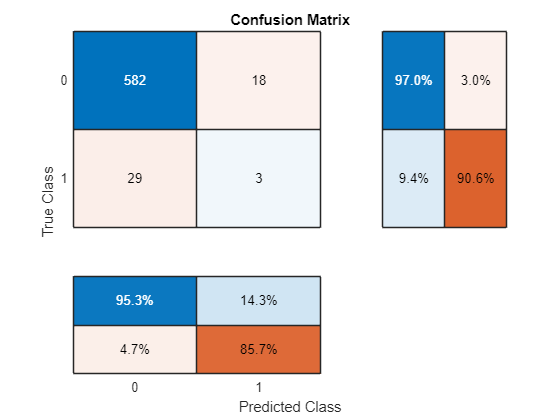


%% Evaluate Model Performance and Plot AUC-ROC and Confusion Matrix

% Classify validation images and get scores
[YPred, scores] = classify(trainedNet, augimdsValidation);
YValidation = imdsValidation.Labels;

% Plot confusion matrix
figure;
confusionchart(YValidation, YPred, 'Title', 'Confusion Matrix', ...
               'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized');

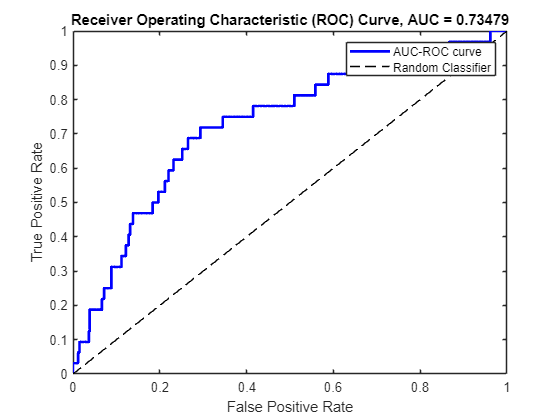


% Extract probabilities for the positive class
scoresNormalized = scores(:, 2);  % Extract positive class probabilities

% Compute ROC curve and AUC
positiveClass = categorical("1");  % Adjust if needed
YValidationNumeric = double(YValidation == positiveClass);
[fpr, tpr, ~, aucValue] = perfcurve(YValidationNumeric, scoresNormalized, 1);

% Plot ROC curve
figure;
plot(fpr, tpr, 'b-', 'LineWidth', 2);
hold on;
plot([0 1], [0 1], 'k--');  % Diagonal line for random classifier
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title(['Receiver Operating Characteristic (ROC) Curve, AUC = ' num2str(aucValue)]);
legend('AUC-ROC curve', 'Random Classifier');
hold off;